# LAB 1 - Zakary Steenhoek - MAT 275

# Exercise 1

Define input variable theta as discretized row vector (i.e. array)

theta =[0, pi/6, pi/4, pi/3, (4*pi)/3, (5*pi)/4, (6*pi)/6];

Define radius

r=5;

Define x and y in terms of theta and r

x= r*cos(theta);
y= r*sin(theta);

Check that x and y satisfy the equation of a circle

r=sqrt(x.^2+y.^2)

r =     5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000


**Explain results here.** Do x and y satisfy the equation of a circle? Why or why not?

How does the vector output at the end confirm your answer?

The vector output after computing r comfirm that the equations of x and y satisfy the equation of a circle since the radius at all the major radian fractions is 5.0000.

# Exercise 2

Define t-vector

t=(4:0.2:20);

Define y-vector

y=(exp(t/10).*cos(t.*2))./(0.2.*(t.^3)+6);

### Part (a)

Plot results (should have 3 plots total)

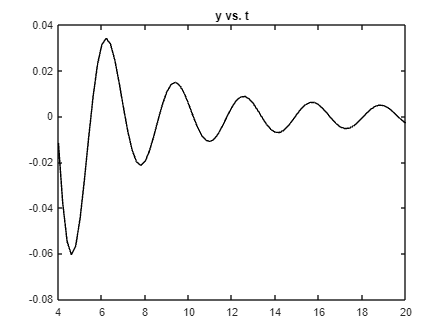

figure;
plot(t,y,'k-');
title('y vs. t');

### Part (b)

Plot results as data points only and as data points with line.

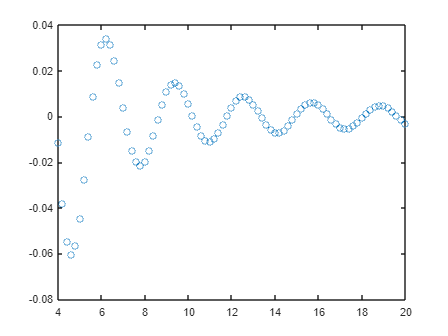

figure %creates another figure window
plot(t,y,'o');

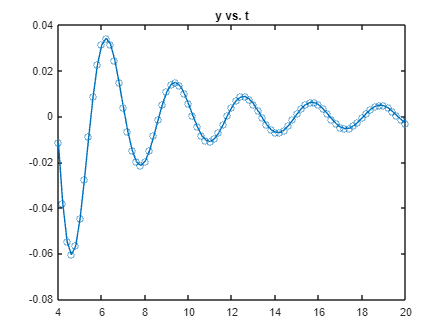

plot(t,y,'o-');
title('y vs. t');

# Exercise 3

Create t-vector (choose enough elements so that plot is smooth!)

t = 0:0.01:5;

Define x, y, x components in terms of t

x = 6.*cos(7.*t); y = 6.*sin(7.*t); z = 3.*t;

Plot results

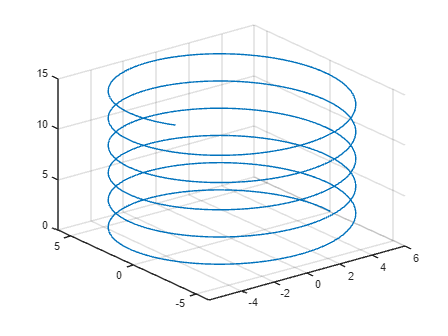

figure;
plot3(x,y,z);
grid on;

# Exercise 4

Define input variable as vector

x= -pi/6:0.01:pi/6;

Define y and z

y = sin(6*x);
z = 6*x-36*x.^3;

Plot results

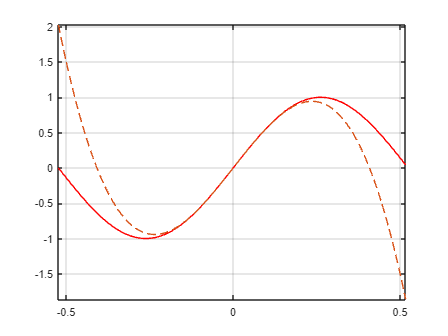

figure;
plot(x,y,'r',x,z,'--');
axis tight;
grid on

# Exercise 5

type ex5.m

clear;
clc;
x = 0:0.01:9; % define the vector x in the interval [0 ,9]
y1 = f(x,270); % compute the solution with C = 270
y2 = f(x,440); % compute the solution with C = 440
y3 = f(x,660); % compute the solution with C = 660
plot(x,y1,'g--',x,y2,'b:',x,y3,'c-.'); % plot the three solutions with different line - styles
title('Solutions to dy/dx = −21x − 2x2 + 20 cos(x)'); % add a title
legend('270','440','660'); % add a legend

function y = f(x,C)
y = -(21/2)*x.^2-(2/3)*x.^3+20*sin(x)+C;% fill - in with the expression for the general solution
end


Run your M-file--i.e. execute the M-file

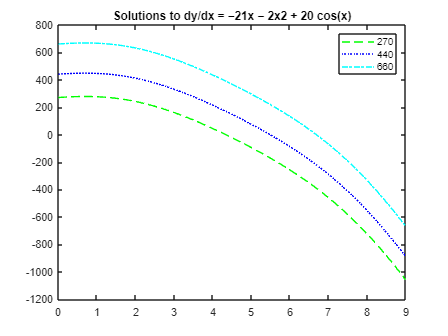

run 'ex5.m'

# Exercise 6

### Part (a)

Define g as anonymous function

g=@(x,y)(x.^5/y.^3)+(cos(7.*x.*exp(6.*y)))./((x.^6)+3);

Evaluate g at the given values of x and y

g(-4,-5)

ans = 8.1922

### Part (b)

Clear the function g out of the workspace

clear g;

Print out g.m contents

type 'g.m'

function f=g(x,y)
    f=(x.^5/y.^3)+(cos(7.*x.*exp(6.*y)))./((x.^6)+3);
end


Evaluate g at the given values of x and y

g(-4,-5)

ans = 8.1922

The End!!!